clear

clc

# **Problem (#1)**

Student 1:* 100591752

Student 2:* 100495586

## Data of the problem:

-Spacecraft mass = 2000 kg

-Ground station location: 50 degrees North and 800 m above sea level

-At 22:30, the state of the aircraft with respect to the SEZ reference frame is:

r1=[5369.09; 2332.14; 656.480]

v2=[-3.37027; 4.90364; 0.106703]

-The station crossed the Oxz plane of the ECI reference frame at 9:00

## a)


muE=3.986E5;


% The time passed from 9:00 to 22:30 in hours is 13:30 hours:


t=13.5;

rS=0.8;


% The latitude is passed to radians:

phi=50*pi/180;

% The position r1 and velocity v1:

rP_2_SEZ=[5369.09; 2332.14; 656.480];

vP_2_SEZ=[-3.37027; 4.90364; 0.106703];

r1=rP_2_SEZ;

v1=vP_2_SEZ;


% SEZ2ECI function is used to get the position and velocity at the ECI reference

% frame:


[r0,v0] =SEZ2ECI(r1,v1,rS,phi,t);

fprintf('\n--- Part (a) Results ---\n');


--- Part (a) Results ---



fprintf(' r0 = [%.5f, %.5f, %.5f] km\n', r0(1), r0(2), r0(3));

 r0 = [-7081.21219, -5457.42427, 1932.79031] km



fprintf(' v0 = [%.5f, %.5f, %.5f] km/s\n', v0(1), v0(2), v0(3));

 v0 = [4.59530, -4.08358, 2.24811] km/s


## b)

r_vec = r0;

v_vec = v0;


% Having the position and velocity, rv2coe function is used to get the classical

% orbital elements:

[a, e, i_rad, Omega_rad, omega_rad, nu_rad] = rv2coe(r_vec, v_vec, muE);

COE_part_b=[a, e, i_rad*180/pi, Omega_rad*180/pi, omega_rad*180/pi, nu_rad*180/pi];


% In order to show all the angles between -180 and 180 degrees:

if COE_part_b(3) > 180

COE_part_b(3)=COE_part_b(3)-360;

end

if COE_part_b(4) > 180

COE_part_b(4)=COE_part_b(4)-360;

end

if COE_part_b(5) > 180

COE_part_b(5)=COE_part_b(5)-360;

end

if COE_part_b(6) > 180

COE_part_b(6)=COE_part_b(6)-360;

end

fprintf('\n--- Part (b) Results ---\n');


--- Part (b) Results ---



fprintf('\n--- Classical orbital elements (COEs) ---\n');


--- Classical orbital elements (COEs) ---



fprintf('Semi-major axis (a): %.4f km\n', COE_part_b(1));

Semi-major axis (a): 8995.6258 km



fprintf('Eccentricity (e): %.6f\n', COE_part_b(2));

Eccentricity (e): 0.100106



fprintf('Inclination (i): %.4f deg\n', COE_part_b(3));

Inclination (i): 25.0051 deg



fprintf('RAAN (Omega): %.4f deg\n', COE_part_b(4));

RAAN (Omega): -169.9931 deg



fprintf('Argument of periapsis (w): %.4f deg\n', COE_part_b(5));

Argument of periapsis (w): 135.2704 deg



fprintf('True anomaly (nu): %.4f deg\n', COE_part_b(6));

True anomaly (nu): -105.2767 deg


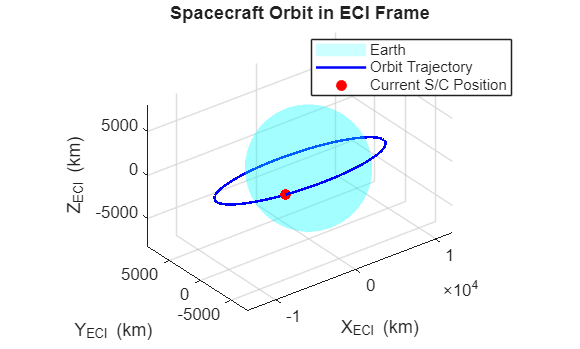


% In order to plot the orbit, first an array of true anomalies is made:


theta_plot = linspace(0, 2*pi, 200);

% The distance (r) is calculated for each true anomaly:

p = a * (1 - e^2); % Semi-latus rectum

r_plot = p ./ (1 + e * cos(theta_plot));

% The coordinates are drawn into the perifocal frame

X_peri = r_plot .* cos(theta_plot);

Y_peri = r_plot .* sin(theta_plot);

Z_peri = zeros(1, length(theta_plot)); % Orbit lies flat in the perifocal frame

% The rotation matrix from perifocal to ECI

% The rotaion is (R3(-Omega) * R1(-i) *R3(-omega)):

cw = cos(omega_rad); sw = sin(omega_rad);

cO = cos(Omega_rad); sO = sin(Omega_rad);

ci = cos(i_rad); si = sin(i_rad);

Q_pX = [cO*cw - sO*ci*sw, -cO*sw - sO*ci*cw, sO*si;

sO*cw + cO*ci*sw, -sO*sw + cO*ci*cw, -cO*si;

si*sw, si*cw, ci];

% The perifocal coordinates are rotated into the ECI reference frame:

r_ECI_orbit = Q_pX * [X_peri; Y_peri; Z_peri];

% Plotting

figure();

hold on; grid on; axis equal;

% The Earth is plotted as a sphere for reference:

[X_E, Y_E, Z_E] = sphere(50);

surf(X_E*6371, Y_E*6371, Z_E*6371, 'EdgeColor', 'none', 'FaceColor', 'c', 'FaceAlpha', 0.2);


% The following curve shows the trajectory:

plot3(r_ECI_orbit(1,:), r_ECI_orbit(2,:), r_ECI_orbit(3,:), 'b-', 'LineWidth', 1.5);

% The following shows the spacecraft's position at the observation time:

plot3(r0(1), r0(2), r0(3), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');

xlabel('X_{ECI} (km)'); ylabel('Y_{ECI} (km)'); zlabel('Z_{ECI} (km)');

title('Spacecraft Orbit in ECI Frame');

legend('Earth', 'Orbit Trajectory', 'Current S/C Position');

view(3);

hold off;

## **c)**

% c.1) Local time when the spacecraft reaches theta = theta_0 + pi/2

% The current eccentric anomaly (E_0) and new true anomaly (nu_1) are first

% calculated:

nu_0 = nu_rad; % From part b

nu_1 = nu_0 + pi/2;

% Because nu_0 is not equal to 0, the time that has passed from the orbit pericenter

% to nu_0 needs to be calculated, named as tfromP:

ne=sqrt(muE/a^3);

E0=theta2E(nu_0,e);

M_0=E0-e*sin(E0);

tfromP=M_0/ne;

% Now the time that has passed from nu_0 to nu_0 + pi/2 is calculated:

theta = nu_1;

E = theta2E(theta, e);

M = E - e * sin(E);

tfromPdef = M/ne-tfromP; % time from theta0 to current theta (time from theta0 to theta minus time from pericenter to theta0)

delta_t1_sec=tfromPdef;

delta_t1_hr = delta_t1_sec / 3600;

% The new local time is calculated:

local_time_initial = 22.5; % Initial observation at 22:30

local_time_new_hr = mod(local_time_initial + delta_t1_hr, 24);

% Time is converted to decimal hours to HH:MM:SS format for displaying

hrs = floor(local_time_new_hr);

mins = floor((local_time_new_hr - hrs) * 60);

secs = round((local_time_new_hr - hrs - mins/60) * 3600);
fprintf('\n--- Part (c) Results ---\n');


--- Part (c) Results ---



fprintf('1. Local time at theta = theta_0 + pi/2 is: %02d:%02d:%02d (next day if past midnight)\n', hrs, mins, secs);

1. Local time at theta = theta_0 + pi/2 is: 23:02:03 (next day if past midnight)



% c.2) Position and velocity in ECI 6 hours later

% First the time that has passed from crossing the pericenter to nu_0 (initial

% observation) is calculated:

t0=M_0/ne;

% The 6 hours are added to the initial time:

t1=6*3600+t0;

% Newton method is used to iterate the E:

M1=ne*t1;

Eguess=M1;

fE= @(E) E - e*sin(E) - ne*t1;

dfE= @(E) 1-e*cos(E);

tol=10^-8;

maxiter=100;

Eattime=newton(fE,dfE,Eguess,tol,maxiter);

The number of iterations is 2


nu_2=E2theta(Eattime,e);

% Now that the true anomaly has changed, the position and velocity need to be

% recalculated using the new orbital elements (true anomaly):

p_semi = a * (1 - e^2); % Semi-latus rectum

[r_ECI_6h, v_ECI_6h] = coe2rv(muE, p_semi, e, i_rad, Omega_rad, omega_rad, nu_2);

fprintf('\n 2. State in ECI 6 hours later:\n');


 2. State in ECI 6 hours later:



fprintf(' r0 = [%.3f, %.3f, %.3f] km\n', r_ECI_6h(1), r_ECI_6h(2), r_ECI_6h(3));

 r0 = [2073.667, 8266.364, -3628.842] km



fprintf(' v0 = [%.5f, %.5f, %.5f] km/s\n', v_ECI_6h(1), v_ECI_6h(2), v_ECI_6h(3));

 v0 = [-6.11264, 1.67138, -1.26311] km/s



% c.3) Compute state in SEZ after 6 hours

% The time that has passed since Oxz crossing is initial t (13.5h) + 6 hours:

t_6h = t + 6; % In hours

t=t_6h;

r0=r_ECI_6h;

v0=v_ECI_6h;

% Applying ECI2SEZ function:

[r1, v1] = ECI2SEZ(r0, v0, rS, phi, t);

r_SEZ_6h=r1;

v_SEZ_6h=v1;

fprintf('3. State in SEZ 6 hours later:\n');

3. State in SEZ 6 hours later:



fprintf(' r1 = [%.3f, %.3f, %.3f] km\n', r_SEZ_6h(1), r_SEZ_6h(2), r_SEZ_6h(3));

 r1 = [-2909.901, 5079.220, -13550.614] km



fprintf(' v1 = [%.5f, %.5f, %.5f] km/s\n', v_SEZ_6h(1), v_SEZ_6h(2), v_SEZ_6h(3));

 v1 = [-1.87996, -4.51006, -3.22634] km/s


## d)

% The initial mass is 2000 kg:

m = 2000; % Initial spacecraft mass

% The payload mass is 500 kg:

m_payload = 500; % Payload mass

% Then the remaining aircraft mass is:

m_sc_new = 1500; % Remaining spacecraft mass (2000 - 500)

% The payload velocity in ECI is:

v_payload = [-6.0; 3.0; -1.6]; % km/s

% Ensure v_ECI_6h is a column vector to prevent matrix dimension errors

if size(v_ECI_6h, 2) > 1

v_ECI_6h = v_ECI_6h';

end

% Conservation of linear momentum is applied to find the new spacecraft velocity:

v_sc_new = (m * v_ECI_6h - m_payload * v_payload) / m_sc_new;

% Position remains identical instantaneously because the separation takes place

% in a very small amount of time.

r_sc_new = r_ECI_6h;

if size(r_sc_new, 2) > 1

r_sc_new = r_sc_new';

end

% Because the velocity and position have changed, the new classical orbital

% elements are calculated using rv2coe:

[a_new, e_new, i_new_rad, Omega_new_rad, omega_new_rad, nu_new_rad] = rv2coe(r_sc_new, v_sc_new, muE);

% Convert angles to degrees for display

i_new_deg = i_new_rad * 180/pi;

Omega_new_deg = Omega_new_rad * 180/pi;

omega_new_deg = omega_new_rad * 180/pi;

nu_new_deg = nu_new_rad * 180/pi;

if i_new_deg >180

i_new_deg=i_new_deg-360;

end

if Omega_new_deg >180

Omega_new_deg=Omega_new_deg-360;

end

if omega_new_deg >180

omega_new_deg=omega_new_deg-360;

end

if nu_new_deg >180

nu_new_deg=nu_new_deg-360;

end

% --- SHOW RESULTS ---
fprintf('\n--- Part (d) Results ---\n');


--- Part (d) Results ---



fprintf('New Spacecraft Velocity after release:\n');

New Spacecraft Velocity after release:



fprintf(' v_sc_new = [%.5f, %.5f, %.5f] km/s\n', v_sc_new(1), v_sc_new(2), v_sc_new(3));

 v_sc_new = [-6.15019, 1.22850, -1.15081] km/s



fprintf('\n--- New Classical Orbital Elements (Post-Release) ---\n');


--- New Classical Orbital Elements (Post-Release) ---



fprintf('Semi-major axis (a): %.4f km\n', a_new);

Semi-major axis (a): 8778.7000 km



fprintf('Eccentricity (e): %.6f\n', e_new);

Eccentricity (e): 0.061268



fprintf('Inclination (i): %.4f deg\n', i_new_deg);

Inclination (i): 25.2827 deg



fprintf('RAAN (Omega): %.4f deg\n', Omega_new_deg);

RAAN (Omega): -168.4358 deg



fprintf('Argument of periapsis (w): %.4f deg\n', omega_new_deg);

Argument of periapsis (w): 90.8535 deg



fprintf('True anomaly (nu): %.4f deg\n', nu_new_deg);

True anomaly (nu): 155.6793 deg


## e)

% Using the semi-major axis (a_new) and eccentricity (e_new) from part (d),

% the new radius of pericenter is obtained:

r_p = a_new * (1 - e_new);

% Using the Vis-Viva equation, the velocity at the pericenter is found:

v_p_elliptical = sqrt(muE * (2/r_p - 1/a_new));

% The velocity required for a circular orbit with that same radius is calculated:

% For a circular orbit, v = sqrt(mu/r)

v_p_circular = sqrt(muE / r_p);

% Finally, it is computed the delta-V required to circularize the orbit. Since

% both velocities are strictly tangential at pericenter, we just subtract their

% magnitudes.

delta_V = abs(v_p_circular - v_p_elliptical);

% --- SHOW RESULTS ---
fprintf('\n--- Part (e) Results ---\n');


--- Part (e) Results ---



fprintf('Radius of new pericenter (r_p): %.4f km\n', r_p);

Radius of new pericenter (r_p): 8240.8451 km



fprintf('Velocity at pericenter (current): %.5f km/s\n', v_p_elliptical);

Velocity at pericenter (current): 7.16466 km/s



fprintf('Velocity for circular orbit: %.5f km/s\n', v_p_circular);

Velocity for circular orbit: 6.95477 km/s



fprintf('Required Delta-V to circularize: %.5f km/s\n', delta_V);

Required Delta-V to circularize: 0.20989 km/s


## Discussion

This exercise successfully modeled the trajectory, time propagation, and impulsive maneuvers of a 2000 kg spacecraft in Earth orbit.

**Initial Orbit (Parts a & b):** By transforming the topocentric SEZ observation into the inertial ECI frame, we determined the spacecraft's initial orbit. The resulting Classical Orbital Elements reveal a relatively low-eccentricity orbit ($e \approx 0.1001$) with a semi-major axis of $a \approx 8995.6$ km and an inclination of $25^\circ$. As verified by the 3D plot, the orbit is elliptical but visually quite close to circular.

**Time Propagation (Part c):** Using Kepler's equation, we propagated the spacecraft's state 6 hours forward. Because the eccentricity is small, the Newton-Raphson numerical method was highly efficient, converging on the new eccentric anomaly in just 2 iterations. This gave us the exact new state vectors and local time (23:02:03) at the required future true anomaly.

**Payload Separation (Part d):** The instantaneous release of a 500 kg payload was calculated using the conservation of linear momentum. Because the payload was ejected with a specific velocity vector, the remaining 1500 kg spacecraft experienced a reactive change in velocity. This maneuver fundamentally altered its orbit, decreasing both its semi-major axis (to $8778.7$ km) and its eccentricity (dropping to $0.0613$).

**Circularization Maneuver (Part e):** Finally, we calculated the cost to circularize the new orbit at its pericenter ($r_p \approx 8240.8$ km). Because a maneuver at an apsidal point only requires a change in velocity magnitude (not direction), we used the scalar difference from the Vis-Viva equation. The current velocity at pericenter was $7.164$ km/s, while a circular orbit required $6.955$ km/s. The required $\Delta V$ is therefore $\approx 0.2099$ km/s. This relatively small required "burn" makes perfect physical sense, as the post-release orbit was already highly circular ($e \approx 0.061$).

## AI Declaration

We declare that we have generative AI for the plot of part b), specially the generation of the sphere (code lines 146-148), as we were not familiarized with the plotting of surfaces.